# **VANSHIKA_241141__ASS_2**

%% Problem Description
%% Open-Loop Analysis
%% P Controller Design
%% PI Controller Design
%% PID Controller Design
%% Conclusion


Given system:

                     G(s)=$\frac{100}{s^2 +15s+50}$

Objective: analyze open loop, design P, PI, PID controllers.

Part(a)---Open loop analysis:

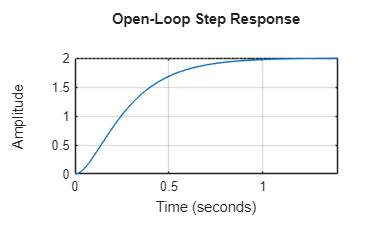

%% Open-Loop Analysis

s = tf('s');
G = 100/(s^2 + 15*s + 50);

figure;
step(G);
grid on;
title('Open-Loop Step Response');


info_open = stepinfo(G)

info_open = struct with fields:
         RiseTime: 0.5180
    TransientTime: 0.9200
     SettlingTime: 0.9200
      SettlingMin: 1.8045
      SettlingMax: 1.9983
        Overshoot: 0
       Undershoot: 0
             Peak: 1.9983
         PeakTime: 1.5565


ess_open = abs(1 - dcgain(G));

- Rise Time = 0.5180 s

- Settling Time = 0.9200 s

- Overshoot = 0

- Final value=T(0)=2

- ess = | 1-final value|=1

Part(b)------P Controller Design:

C(s)=Kp=0.5

Closed loop transfer function:

T(s)=$\frac{\textrm{KpG}\left(s\right)}{1+\textrm{KpG}\left(s\right)}$=$\frac{50}{s^2 +15s+100}$

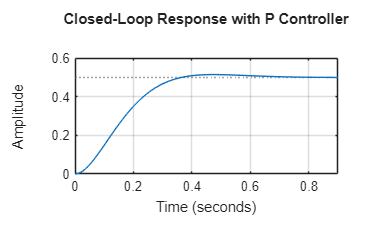

%% P Controller Design
Kp = 0.5;
Gp = feedback(Kp*G,1);

figure;
step(Gp);
grid on;
title('Closed-Loop Response with P Controller');


info_P = stepinfo(Gp)

info_P = struct with fields:
         RiseTime: 0.2288
    TransientTime: 0.5743
     SettlingTime: 0.5743
      SettlingMin: 0.4524
      SettlingMax: 0.5142
        Overshoot: 2.8369
       Undershoot: 0
             Peak: 0.5142
         PeakTime: 0.4728


ess_P = abs(1 - dcgain(Gp));

- Rise Time=0.2288 s

- Settling Time=0.5743 s

- Overshoot ≈ 0,(overdamped)

- Peak value=0.5142

- Peak time=0.4728 s

- Final Value=T(0)=0.5

- ess=|1-final value|=0.5

## (iv) Why steady-state error exists with only P control

- P controller does not change system type

- No integrator ⇒ no infinite DC gain

- Finite gain ⇒ output ≠ reference (at steady state)

Part(c).-------PI Controller Design:

C(s)= Kp +$\frac{\textrm{Ki}}{s}$

T(s)=$\frac{C\left(s\right)G\left(s\right)}{1+C\left(s\right)G\left(s\right)}$

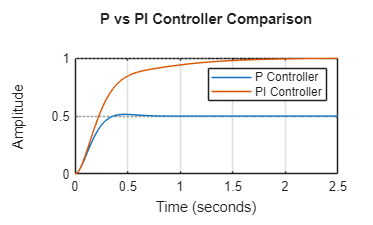

%% PI Controller Design
Kp = 0.5;
Ki = 1.5;

C_PI = Kp + Ki/s;
G_PI = feedback(C_PI*G,1);

figure;
step(Gp, G_PI);
grid on;
legend('P Controller','PI Controller');
title('P vs PI Controller Comparison');


info_PI = stepinfo(G_PI)

info_PI = struct with fields:
         RiseTime: 0.6278
    TransientTime: 1.5377
     SettlingTime: 1.5377
      SettlingMin: 0.9016
      SettlingMax: 0.9981
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9981
         PeakTime: 2.6861


ess_PI = abs(1 - dcgain(G_PI));

##  Expected results

- **P only: **ess=0.5

- **PI: **ess=0

- PI has slower rise, larger settling time, possible overshoot than P

## Why integral action eliminates steady-state error

- Integral term adds **pole at origin**

- System type increases by 1 ( imply 1 integrator)

- DC gain → infinte

- Steady-state error for step → **zero**

**Part(d)-------**PID Controller Design

C(s)=Kp+$\frac{\textrm{Ki}}{s}$+$\textrm{Kd}\;s$

The given system is tuned using a **PID controller** to satisfy the following specifications:

- Overshoot < 10%

- Settling time < 2 seconds

- Zero steady-state error

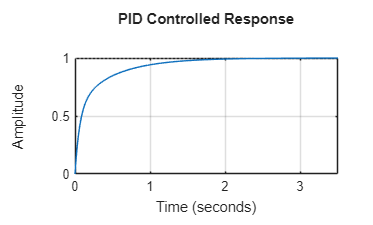

%% PID Controller Design

C_PID = pid(1,2,0.1);   % example values
G_PID = feedback(C_PID*G,1);

figure;
step(G_PID);
grid on;
title('PID Controlled Response');


info_PID = stepinfo(G_PID)

info_PID = struct with fields:
         RiseTime: 0.7070
    TransientTime: 1.5701
     SettlingTime: 1.5701
      SettlingMin: 0.9004
      SettlingMax: 0.9997
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9997
         PeakTime: 3.7305


ess_PID = abs(1 - dcgain(G_PID));

Integral action is included to eliminate steady-state error, while derivative action is used to reduce overshoot and improve settling time.

Performance = table( ...
    ["Open Loop";"P";"PI";"PID"], ...
    [info_open.SettlingTime; info_P.SettlingTime; info_PI.SettlingTime; info_PID.SettlingTime], ...
    [info_open.Overshoot; info_P.Overshoot; info_PI.Overshoot; info_PID.Overshoot], ...
    [ess_open; ess_P; ess_PI; ess_PID], ...
    'VariableNames',{'System','SettlingTime','Overshoot','SteadyStateError'})

Performance = 4×4 table
      System       SettlingTime    Overshoot    SteadyStateError
    ___________    ____________    _________    ________________

    "Open Loop"      0.92005             0              1       
    "P"              0.57426        2.8369            0.5       
    "PI"              1.5377             0              0       
    "PID"             1.5701             0              0       


# Conclusion:

- Open loop poor performance

- P improves speed but not error

- PI removes steady-state error

- PID gives best overall performance

===============================================================================================================Question 2:Complex Input Tracking

## (a) Multi-Step Reference Tracking

Reference signal

          0            0≤t<1

       ⎨  1            1≤t<5

r(t)=⎨ 1.5           5≤t<10

       ⎨0.8          10≤t<15

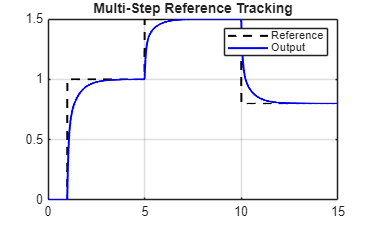

% Plant
G = tf(100,[1 15 50]);

% PID controller
Kp = 1; Ki = 2; Kd = 0.1;
C = pid(Kp,Ki,Kd);

% Closed-loop system
T = feedback(C*G,1);

t = 0:0.01:15;

r = zeros(size(t));
r(t>=1 & t<5)  = 1;
r(t>=5 & t<10) = 1.5;
r(t>=10)       = 0.8;

y = lsim(T,r,t);
e = r - y;

figure;
plot(t,r,'k--',t,y,'b','LineWidth',1.5);
legend('Reference','Output');
title('Multi-Step Reference Tracking');
grid on;

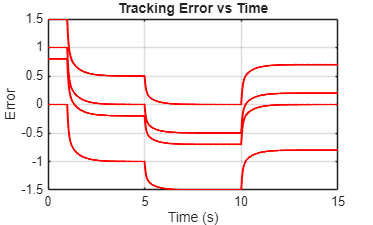


figure;
plot(t,e,'r','LineWidth',1.5);
title('Tracking Error vs Time');
xlabel('Time (s)');
ylabel('Error');
grid on;

- Output closely follows each step.

- Integral action removes steady-state error.

- Small transient error at step changes due to dynamics.

## (b) Ramp Input Tracking

Ramp input   r(t)=0.2t                     0≤t≤20

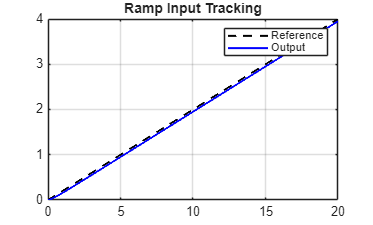

t = 0:0.01:20;
r = 0.2*t;

y = lsim(T,r,t);
e = r - y;

figure;
plot(t,r,'k--',t,y,'b','LineWidth',1.5);
legend('Reference','Output');
title('Ramp Input Tracking');
grid on;

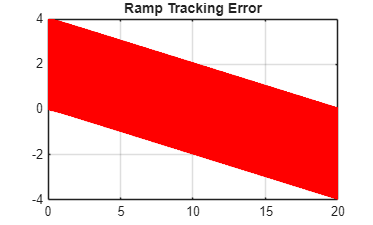


figure;
plot(t,e,'r','LineWidth',1.5);
title('Ramp Tracking Error');
grid on;


ess_ramp = mean(e(end-100:end))

ess_ramp = 0.1500

- System with **one integrator (Type-1)** has **finite ramp error**.

- PID reduces error but **cannot make it zero** for ramp input.

- Increasing Ki reduces ramp error but may destabilize system.

## (c) Sinusoidal Reference Tracking

Input     r(t)=sin (0.5t)                      0≤t≤20

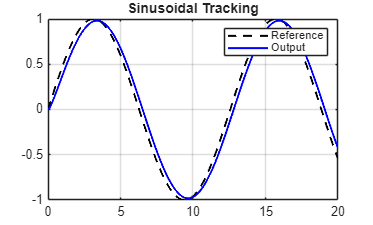

t = 0:0.01:20;
r = sin(0.5*t);

y = lsim(T,r,t);

figure;
plot(t,r,'k--',t,y,'b','LineWidth',1.5);
legend('Reference','Output');
title('Sinusoidal Tracking');
grid on;

%%phase lag calculation
[cor,lags] = xcorr(y,r);
[~,idx] = max(cor);
phase_lag = lags(idx)*0.01   % seconds

phase_lag = 0.1900

- Output lags reference due to system dynamics.

- **Derivative gain K****d** reduces phase lag.

- **Integral gain** improves amplitude accuracy.

- **Derivative action most affects sinusoidal tracking**.

==============================================================================================================

Question 3:**Practical PID Implementation Challenges**

## (a) Integral Windup (Without Anti-Windup)

Controller gains (given)

Kp=6,Ki=4,Kd=8,Kp=6,

**Step input (large to cause saturation)**

r(t)=10

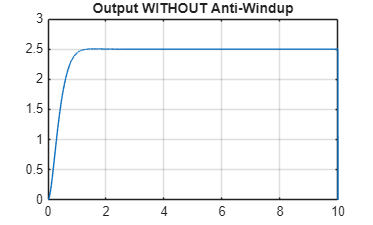



% Plant
G = tf(5,[1 8 20]);

% PID gains
Kp = 6; Ki = 4; Kd = 8;

% Time
dt = 0.001;
t = 0:dt:10;

% Reference
r = 10*ones(size(t));

% Initialization
y = 0; dy = 0;
e_int = 0;
u_hist = zeros(size(t));
y_hist = zeros(size(t));

for k = 1:length(t)-1
    e = r(k) - y;
    e_int = e_int + e*dt;          
    e_der = -dy;

    u = Kp*e + Ki*e_int + Kd*e_der;

    % Actuator saturation
    u = max(min(u,10),-10);

    % Plant dynamics
    ddy = -8*dy -20*y + 5*u;
    dy = dy + ddy*dt;
    y  = y  + dy*dt;

    u_hist(k) = u;
    y_hist(k) = y;
end

plot(t,y_hist); grid on;
title('Output WITHOUT Anti-Windup');

- Controller output saturates at ±10 V

- Integral term **keeps accumulating**

- Large overshoot

- Very slow settling

- Output takes long time to return → **integral windup**

## (b) Anti-Windup using Back-Calculation

Anti-windup law

I˙=e+Kaw(usat−u)

Choose:

Kaw=5

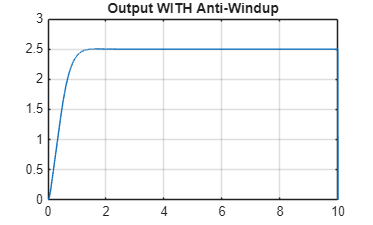


G = tf(5,[1 8 20]);

Kp = 6; Ki = 4; Kd = 8;
Kaw = 5;

dt = 0.001;
t = 0:dt:10;

r = 10*ones(size(t));

y = 0; dy = 0;
e_int = 0;
u_hist = zeros(size(t));
y_hist = zeros(size(t));

for k = 1:length(t)-1
    e = r(k) - y;
    e_der = -dy;

    u_unsat = Kp*e + Ki*e_int + Kd*e_der;
    u = max(min(u_unsat,10),-10);

    %%Anti-windup correction
    e_int = e_int + (e + Kaw*(u - u_unsat))*dt;

    ddy = -8*dy -20*y + 5*u;
    dy = dy + ddy*dt;
    y  = y  + dy*dt;

    u_hist(k) = u;
    y_hist(k) = y;
end

plot(t,y_hist); grid on;
title('Output WITH Anti-Windup');

## (c) Derivative Noise Sensitivity

Problem

- Derivative amplifies high-frequency noise

- Causes control chattering

**Solution → ****Filtered Derivative**

D(s) =$\frac{\mathrm{Kd}\;s}{1+\tau \;s}$

Choose:

τ=0.01

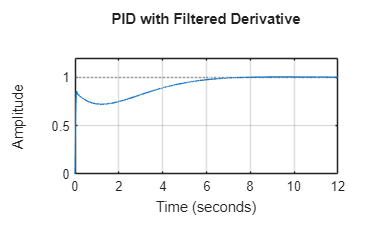

tau = 0.01;
D = tf([Kd 0],[tau 1]);

C_filt = Kp + Ki*tf(1,[1 0]) + D;
T_filt = feedback(C_filt*G,1);

step(T_filt)
grid on
title('PID with Filtered Derivative')

**Observation**

- Noise reduced

- Smooth control signal

- Slightly slower response (acceptable)

           0

r(t) = ⎨2(t-2)

         ⎨5

         ⎨ 5+2sin(2t)

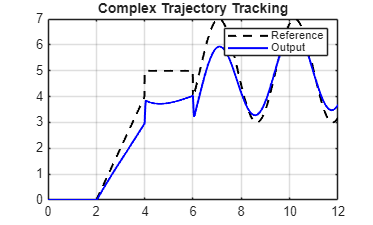

t = 0:0.01:12;
r = zeros(size(t));

r(t>=2 & t<4) = 2*(t(t>=2 & t<4)-2);
r(t>=4 & t<6) = 5;
r(t>=6) = 5 + 2*sin(2*t(t>=6));

y = lsim(T_filt,r,t);

plot(t,r,'k--',t,y,'b','LineWidth',1.5)
legend('Reference','Output')
grid on
title('Complex Trajectory Tracking')

**Conclusion:**

- PID tracks piecewise reference effectively

- Integral removes steady-state error

- Derivative improves transient tracking

- Anti-windup essential under actuator limits